## SIOC 221A HW 2

## Kevin Okun

### Problem 1

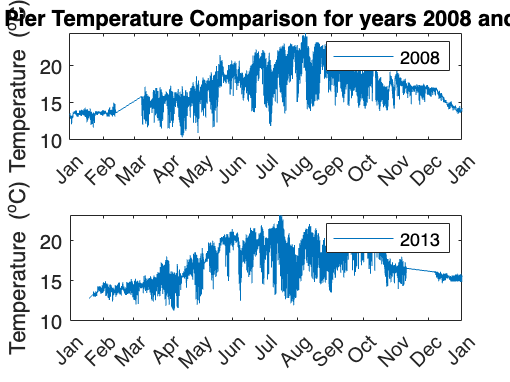

% Load data from last HW
% Default is on KO's machine, so specify path below if needed or load from
% the .mat file on github, "KO_HW1_Data.mat"
direc_str = '/Users/kevinokun/Documents/GitHub/SIO221a_Github_code/homework1_code/okun_homework1_code';
cd(direc_str)
load('KO_HW1_Data.mat');
clearvars direc_str

% Choose two years to compare
years = [2008 2013];
year_names = string(char({['year_',num2str(years(1))], ['year_',num2str(years(2))]}));

% Plot temperature and pressure from the two years
figure
subplot 211
plot(pier.([year_names(1)]).time,pier.(year_names(1)).temperature)
ylabel('Temperature (^oC)')
datetick('x','mmm')
legend(num2str(years(1)))
title(['SIO Pier Temperature Comparison for years ', num2str(years(1)), ' and ', num2str(years(2))])
subplot 212
plot(pier.([year_names(2)]).time,pier.(year_names(2)).temperature)
ylabel('Temperature (^oC)')
datetick('x','mmm')
legend(num2str(years(2)))

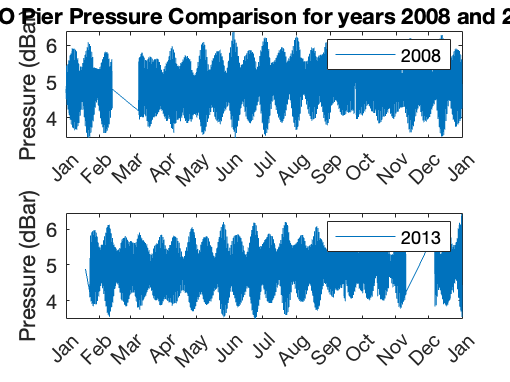


figure
subplot 211
plot(pier.([year_names(1)]).time,pier.(year_names(1)).pressure)
ylabel('Pressure (dBar)')
datetick('x','mmm')
legend(num2str(years(1)))
title(['SIO Pier Pressure Comparison for years ', num2str(years(1)), ' and ', num2str(years(2))])
subplot 212
plot(pier.([year_names(2)]).time,pier.(year_names(2)).pressure)
ylabel('Pressure (dBar)')
datetick('x','mmm')
legend(num2str(years(2)))

Both year's temperature plots follow the same general trend, higher average temperature and higher variability in the summer months than in the winter months. In 2013, however, the peak temperature occurs about a month earlier than in 2008.

Pressure is largely the same between the two years, wit hsome shifts in peak location due to varying starting times in the lunar cycle at the beginning of each year. The amplitudes and means are about the same in either case. Both the pressure and the temperature sensors experienced downtime of about one month over the course of the year.

#### Problem 2

% Calculate standard error of the means of temperature and pressure

for idx = 1:2
    pier.(year_names(idx)).temp_stand_error = (pier.(year_names(idx)).temp_std)/sqrt(length(pier.(year_names(idx)).temperature));
    pier.(year_names(idx)).pressure_stand_error = (pier.(year_names(idx)).pressure_std)/sqrt(length(pier.(year_names(idx)).pressure));
end

% Determine if difference in mean is within standard error for temperature
yearly_temp_difference = abs(pier.(year_names(1)).temp_mean-pier.(year_names(2)).temp_mean);
max_std_error_temp = max(pier.(year_names(1)).temp_stand_error,pier.(year_names(2)).temp_stand_error);

if 1.96*max_std_error_temp >= yearly_temp_difference
    disp('Mean temperature for each year is within standard error.')
else
    disp('Mean temperature for each year is not within standard error')
end

Mean temperature for each year is not within standard error



% Determine if difference in mean is within standard error for pressure
yearly_pressure_difference = abs(pier.(year_names(1)).pressure_mean-pier.(year_names(2)).pressure_mean);
max_std_error_pressure = max(pier.(year_names(1)).pressure_stand_error,pier.(year_names(2)).pressure_stand_error);

if 1.96*max_std_error_pressure >= yearly_pressure_difference
    disp('Mean pressure for each year is within standard error.')
else
    disp('Mean pressure for each year is not within standard error.')
end

Mean pressure for each year is not within standard error.



clearvars yearly_temp_difference max_std_error_temp yearly_pressure_difference max_std_error_pressure

% Same but with subsampled data at 1 year vs every 8 min
downsample_factor = 24*60/8;

% Subsample once a day and repeat calculation of standard error
for idx = 1:2
    pier.(year_names(idx)).temp_subsample = downsample(pier.(year_names(idx)).temperature,downsample_factor);
    pier.(year_names(idx)).temp_subsample_mean = mean(pier.(year_names(idx)).temp_subsample,'omitnan');
    pier.(year_names(idx)).temp_subsample_std = std(pier.(year_names(idx)).temp_subsample,'omitnan');
    pier.(year_names(idx)).temp_subsample_stand_error = (pier.(year_names(idx)).temp_subsample_std)/sqrt(length(pier.(year_names(idx)).temp_subsample));

    pier.(year_names(idx)).pressure_subsample = downsample(pier.(year_names(idx)).pressure,downsample_factor);
    pier.(year_names(idx)).pressure_subsample_mean = mean(pier.(year_names(idx)).pressure_subsample,'omitnan');
    pier.(year_names(idx)).pressure_subsample_std = std(pier.(year_names(idx)).pressure_subsample,'omitnan');
    pier.(year_names(idx)).pressure_subsample_stand_error = (pier.(year_names(idx)).pressure_subsample_std)/sqrt(length(pier.(year_names(idx)).pressure_subsample));
end

% Determine if difference in mean is within standard error for temperature
daily_temp_difference = abs(pier.(year_names(1)).temp_subsample_mean-pier.(year_names(2)).temp_subsample_mean);
max_std_error_temp_sub = max(pier.(year_names(1)).temp_subsample_stand_error,pier.(year_names(2)).temp_subsample_stand_error);

if 1.96*max_std_error_temp_sub >= daily_temp_difference
    disp('Mean subsampled temperature for each year is within standard error.')
else
    disp('Mean subsampled temperature for each year is not within standard error.')
end

Mean subsampled temperature for each year is not within standard error.



% Determine if difference in mean is within standard error for pressure
daily_pressure_difference = abs(pier.(year_names(1)).pressure_subsample_mean-pier.(year_names(2)).pressure_subsample_mean);
max_std_error_pressure_sub = max(pier.(year_names(1)).pressure_subsample_stand_error,pier.(year_names(2)).pressure_subsample_stand_error);

if 1.96*max_std_error_pressure_sub >= daily_pressure_difference
    disp('Mean subsampled pressure for each year is within standard error.')
else
    disp('Mean subsampled pressure for each year is not within standard error.')
end

Mean subsampled pressure for each year is within standard error.



clearvars daily_temp_difference max_std_error_temp_sub daily_pressure_difference max_std_error_pressure_sub downsample_factor idx

With 95% confidence, the temperature is not within standard error for both the full data set and for data subsampled once per day. The pressure, however, goes from not being within error to within error once it is subsampled. 

#### Problem 3

% Calculate standard error of variance

for idx = 1:2
    pier.(year_names(idx)).temp_stand_error_var = (pier.(year_names(idx)).temp_std)^2*sqrt(2/(length(pier.(year_names(idx)).temperature)-1));
    pier.(year_names(idx)).pressure_stand_error_var = (pier.(year_names(idx)).pressure_std)^2*sqrt(2/(length(pier.(year_names(idx)).pressure)-1));
end

% Determine if difference in variance is within standard error for temperature
yearly_temp_difference = abs(pier.(year_names(1)).temp_std-pier.(year_names(2)).temp_std);
max_std_error_temp = max(pier.(year_names(1)).temp_stand_error_var,pier.(year_names(2)).temp_stand_error_var);

if 1.96*max_std_error_temp >= yearly_temp_difference
    disp('Temperature variance for each year is within standard error.')
else
    disp('Temperature variance for each year is not within standard error')
end

Temperature variance for each year is not within standard error



% Determine if difference in variance is within standard error for pressure
yearly_pressure_difference = abs(pier.(year_names(1)).pressure_std-pier.(year_names(2)).pressure_std);
max_std_error_pressure = max(pier.(year_names(1)).pressure_stand_error_var,pier.(year_names(2)).pressure_stand_error_var);

if 1.96*max_std_error_pressure >= yearly_pressure_difference
    disp('Pressure variance for each year is within standard error.')
else
    disp('Pressure variance for each year is not within standard error.')
end

Pressure variance for each year is not within standard error.



clearvars yearly_temp_difference max_std_error_temp yearly_pressure_difference max_std_error_pressure

% Same but with subsampled data at 1 year vs every 8 min
downsample_factor = 24*60/8;

% Subsample once a day and repeat calculation of standard error
for idx = 1:2
    pier.(year_names(idx)).temp_subsample_stand_error_var = (pier.(year_names(idx)).temp_subsample_std)^2/sqrt(2/(length(pier.(year_names(idx)).temp_subsample)-1));

    pier.(year_names(idx)).pressure_subsample_stand_error_var = (pier.(year_names(idx)).pressure_subsample_std)^2/sqrt(2/(length(pier.(year_names(idx)).pressure_subsample)-1));
end

% Determine if difference in mean is within standard error for temperature
daily_temp_difference = abs(pier.(year_names(1)).temp_subsample_std-pier.(year_names(2)).temp_subsample_std);
max_std_error_temp_sub = max(pier.(year_names(1)).temp_subsample_stand_error_var,pier.(year_names(2)).temp_subsample_stand_error_var);

if 1.96*max_std_error_temp_sub >= daily_temp_difference
    disp('Standard deviation of subsampled temperature for each year is within standard error.')
else
    disp('Standard deviation of subsampled temperature for each year is not within standard error.')
end

Standard deviation of subsampled temperature for each year is within standard error.



% Determine if difference in mean is within standard error for pressure
daily_pressure_difference = abs(pier.(year_names(1)).pressure_subsample_std-pier.(year_names(2)).pressure_subsample_std);
max_std_error_pressure_sub = max(pier.(year_names(1)).pressure_subsample_stand_error_var,pier.(year_names(2)).pressure_subsample_stand_error_var);

if 1.96*max_std_error_pressure_sub >= daily_pressure_difference
    disp('Standard deviation of subsampled pressure for each year is within standard error.')
else
    disp('Standard deviation of subsampled pressure for each year is not within standard error.')
end

Standard deviation of subsampled pressure for each year is within standard error.



clearvars daily_temp_difference max_std_error_temp_sub daily_pressure_difference max_std_error_pressure_sub downsample_factor idx

For the full dataset, neither of the variances are within 95% confidence of each other, while they both are for the subsampled set.

#### Problem 4

% Integrate PDF over range to find total probability of data above 3 sigmas
sigma_level = 3;

% Temperature
for idx = 1:2
    pier.(year_names(idx)).epdf_temp_cdf_prob = 0;
    sigma_threshold = pier.(year_names(idx)).temp_mean + 3*pier.(year_names(idx)).temp_std;
    for idx2 = 1:length(pier.(year_names(idx)).epdf_temp_index)
        pier.(year_names(idx)).epdf_temp_cdf_prob = pier.(year_names(idx)).epdf_temp_cdf_prob + pier.(year_names(idx)).epdf_temp(idx);
        if pier.(year_names(idx)).epdf_temp_cdf_prob >= sigma_threshold
            break
        end
    end
    disp(['The probability of a temperature above 3 sigma for ', num2str(years(idx)), ' is ', num2str(pier.(year_names(idx)).epdf_temp_cdf_prob)])   
end

The probability of a temperature above 3 sigma for 2008 is 9.6751e-05
The probability of a temperature above 3 sigma for 2013 is 0.0003638


disp('The probability of a temperature above 3 sigma for a Gaussian is 0.15')

The probability of a temperature above 3 sigma for a Gaussian is 0.15



% Pressure
for idx = 1:2
    pier.(year_names(idx)).epdf_pressure_cdf_prob = 0;
    sigma_threshold = pier.(year_names(idx)).pressure_mean + 3*pier.(year_names(idx)).pressure_std;
    for idx2 = 1:length(pier.(year_names(idx)).epdf_pressure_index)
        pier.(year_names(idx)).epdf_pressure_cdf_prob = pier.(year_names(idx)).epdf_pressure_cdf_prob + pier.(year_names(idx)).epdf_pressure(idx);
        if pier.(year_names(idx)).epdf_pressure_cdf_prob >= sigma_threshold
            break
        end
    end
    disp(['The probability of a pressure above 3 sigma for ', num2str(years(idx)), ' is ', num2str(pier.(year_names(idx)).epdf_pressure_cdf_prob)]) 
end

The probability of a pressure above 3 sigma for 2008 is 0.0006867
The probability of a pressure above 3 sigma for 2013 is 0.0026947


disp('The probability of a pressure above 3 sigma for a Gaussian is 0.15')

The probability of a pressure above 3 sigma for a Gaussian is 0.15


#### Problem 5

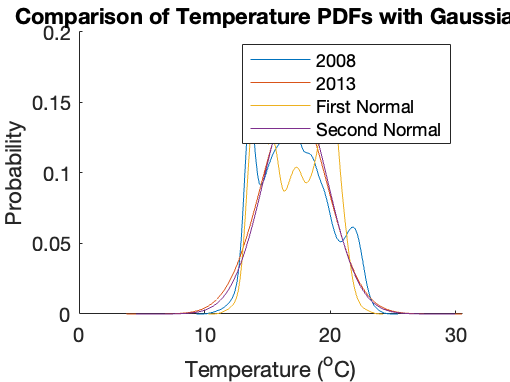

% Plot temperature PDFs with Gaussian and uniform distributions
figure
hold on
for idx = 1:2
    plot(pier.(year_names(idx)).epdf_temp_index,pier.(year_names(idx)).epdf_temp)
    
    % Plot Gaussian
    gauss_range = (-5*pier.(year_names(idx)).temp_std:0.01:5*pier.(year_names(idx)).temp_std) + pier.(year_names(idx)).temp_mean;  %// Plotting range
    gauss = exp(-0.5*((gauss_range - pier.(year_names(idx)).temp_mean)/pier.(year_names(idx)).temp_std).^2)/(pier.(year_names(idx)).temp_std*sqrt(2 * pi));
    plot(gauss_range, gauss)
end
legend(num2str(years(1)), num2str(years(2)), 'First Normal', 'Second Normal')
ylabel('Probability')
xlabel('Temperature (^oC)')
title('Comparison of Temperature PDFs with Gaussian')

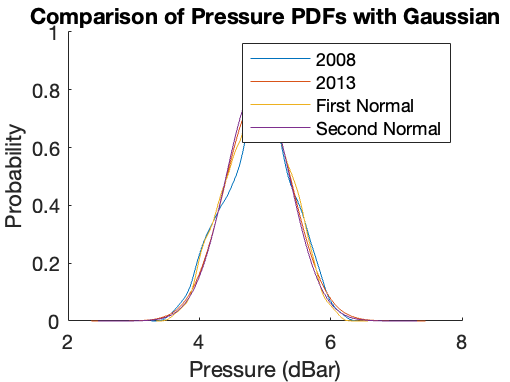


% Plot pressure PDFs with Gaussian and uniform distributions
figure
hold on
for idx = 1:2
    plot(pier.(year_names(idx)).epdf_pressure_index,pier.(year_names(idx)).epdf_pressure)
    
    % Plot Gaussian
    gauss_range = (-5*pier.(year_names(idx)).pressure_std:0.01:5*pier.(year_names(idx)).pressure_std) + pier.(year_names(idx)).pressure_mean;  %// Plotting range
    gauss = exp(-0.5*((gauss_range - pier.(year_names(idx)).pressure_mean)/pier.(year_names(idx)).pressure_std).^2)/(pier.(year_names(idx)).pressure_std*sqrt(2 * pi));
    plot(gauss_range, gauss)
end
legend(num2str(years(1)), num2str(years(2)), 'First Normal', 'Second Normal')
ylabel('Probability')
xlabel('Pressure (dBar)')
title('Comparison of Pressure PDFs with Gaussian')


clearvars gauss gauss_range idx year_names

% Save data to file
cd('/Users/kevinokun/Documents/GitHub/SIO221a_Github_code/homework2_code/okun_homework2_code')
save('KO_HW2_Data','pier')